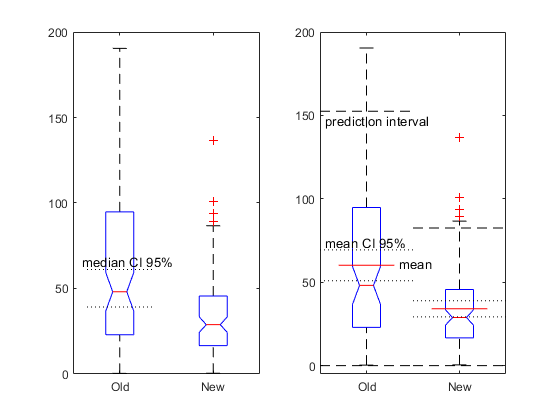

clear all;
close all;

fin = fopen('sgbdold.dat','r');
data_old = fscanf(fin,'%f');
fclose(fin);
fin = fopen('sgbdnew.dat','r');
data_new = fscanf(fin,"%f");
fclose(fin);

n = 100; %size of both datasets

% sample mean with CI at 95% for old and new data
sample_mean_old = mean(data_old);
sample_stddev_old = std(data_old);
sample_mean_new = mean(data_new);
sample_stddev_new = std(data_new);

bound_old = 1.96*sample_stddev_old/sqrt(n);
ci_mean_ub_old = sample_mean_old+bound_old;
ci_mean_lb_old = sample_mean_old-bound_old;

bound_new = 1.96*sample_stddev_new/sqrt(n);
ci_mean_ub_new = sample_mean_new+bound_new;
ci_mean_lb_new = sample_mean_new-bound_new;

% median estimate with CI for old data
data_old_sorted = sort(data_old);
median_estimate = median(data_old_sorted); %quartile Q2
j = floor(0.5*n - 0.980*sqrt(n));
k = ceil(0.5*n+1 + 0.980*sqrt(n));
ci_median_ub = data_old_sorted(k);
ci_median_lb = data_old_sorted(j);

% dispersion computed as 1.5 times the inter quartile range (IQR)
first_quartile = median([data_old_sorted(1):data_old_sorted(floor(median_estimate))]);
third_quartile = median([data_old_sorted(ceil(median_estimate)):data_old_sorted(end)]);
dispersion = (third_quartile - first_quartile)*1.5;

% computation of prediction interval at 95% for old and new data
% data_new_sorted = sort(data_new);
% alpha = 0.05;
% lb = floor((n+1)*alpha/2);
% ub = ceil((n+1)*(1-alpha/2));
% pi_lb_old = data_old_sorted(lb);
% pi_ub_old = data_old_sorted(ub);
% pi_lb_new = data_new_sorted(lb);
% pi_ub_new = data_new_sorted(ub);
%sample_stddev_old = sqrt(sum((data_old-sample_mean_old).^2)/n-1);
pi_lb_old = sample_mean_old - 1.96*sample_stddev_old;
if pi_lb_old < 0
    pi_lb_old = 0;
end
pi_ub_old = sample_mean_old + 1.96*sample_stddev_old;
%sample_stddev_new = sqrt(sum((data_new-sample_mean_new).^2)/n);
pi_lb_new = sample_mean_new - 1.96*sample_stddev_new;
if pi_lb_new < 0
    pi_lb_new = 0;
end
pi_ub_new = sample_mean_new + 1.96*sample_stddev_new;

subplot(1,2,1);
boxplot([data_old,data_new],'Notch','on','Labels',{'Old','New'});
ylim([0 200]);
yticks([0 50 100 150 200]);
%plot median with CI for old data
hold on
plot([0.65,1.35],[ci_median_lb,ci_median_lb],'LineStyle',':','Color','k');
hold on
plot([0.65,1.35],[ci_median_ub,ci_median_ub],'LineStyle',':','Color','k');
text(0.6,ci_median_ub+5,'median CI 95%');
hold off

subplot(1,2,2);
boxplot([data_old,data_new],'Notch','on','Labels',{'Old','New'});
ylim([-5 200]);
yticks([0 50 100 150 200]);
% plot mean with CI for old data
hold on
plot([0.7,1.3],[sample_mean_old,sample_mean_old],'Color','r');
text(1.35,ci_mean_ub_old-8,'mean');
hold on
plot([0,1.5],[ci_mean_lb_old,ci_mean_lb_old],'LineStyle',':','Color','k');
hold on
plot([0,1.5],[ci_mean_ub_old,ci_mean_ub_old],'LineStyle',':','Color','k');
text(0.55,ci_mean_ub_old+5,'mean CI 95%');
%plot prediction interval for old data
hold on
plot([0,1.5],[pi_lb_old,pi_lb_old],'LineStyle','--','Color','k');
hold on
plot([0,1.5],[pi_ub_old,pi_ub_old],'LineStyle','--','Color','k');
text(0.55,pi_ub_old-5,'prediction interval');
% plot mean with CI for new data
hold on
plot([1.7,2.3],[sample_mean_new,sample_mean_new],'Color','r');
hold on
plot([1.5,3],[ci_mean_lb_new,ci_mean_lb_new],'LineStyle',':','Color','k');
hold on
plot([1.5,3],[ci_mean_ub_new,ci_mean_ub_new],'LineStyle',':','Color','k');
%plot prediction interval for old data
hold on
plot([1.5,3],[pi_lb_new,pi_lb_new],'LineStyle','--','Color','k');
hold on
plot([1.5,3],[pi_ub_new,pi_ub_new],'LineStyle','--','Color','k');